# Dynamic programing vs Dynamic programming in optimalisation 

[https://www.youtube.com/watch?v=aPQY__2H3tE&t=1133s](https://www.youtube.com/watch?v=aPQY__2H3tE&t=1133s)

Implementation in the sence of optimisation 

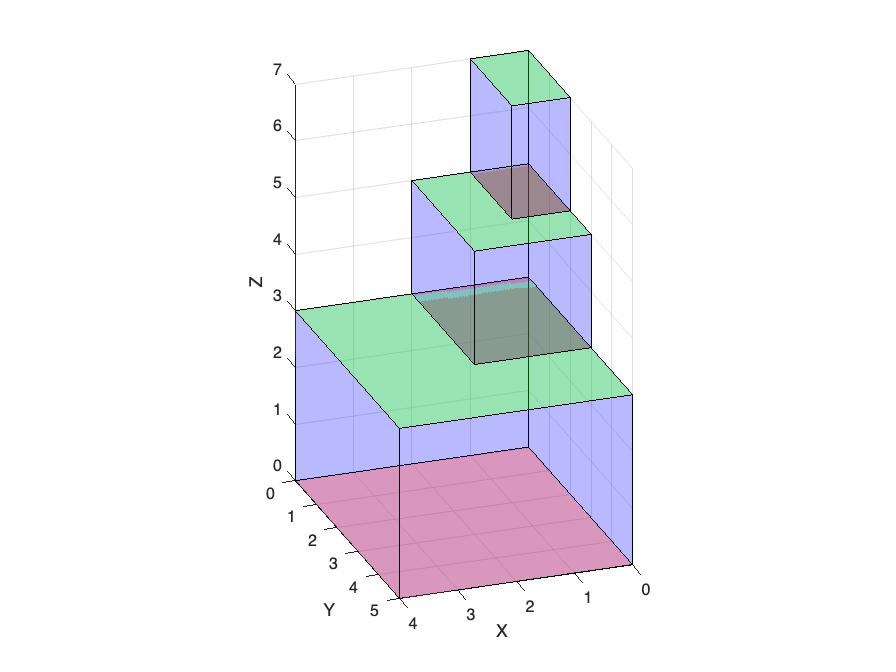

clear;clc;

Boxes = {[4, 5, 3], [1, 5, 4], [2, 3, 2], [2, 4, 1], [3, 6, 2], [1, 2, 2]};

%%% Sort Boxes %%%%%%%%%%%%%%%%%%%%%%%%%%%
widths = cellfun(@(x)x(2), Boxes);
[~, idx] = sort(widths);
Boxes = Boxes(idx);

%%% implementation %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

values = cellfun(@(x)x(3), Boxes);
parents = NaN*zeros(1,length(Boxes));

for i = 1:length(Boxes)

  maximum = values(i);  
  for ii = 1:i-1
    if Boxes{ii}(1) < Boxes{i}(1) && Boxes{ii}(2) < Boxes{i}(2)

      new_max = values(i) + values(ii); 

      if (maximum < new_max)                   
        maximum = new_max;
        parents(i) = ii;
      end

     end
  end
  values(i) = maximum;
end

%%% Extract solution %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[~, row] = max(values);
solution{1}=Boxes{row};
count = 2 ;
next = parents(row);

for i = 1:length(Boxes)
    if(~isnan(next))
        solution{count} = Boxes{next};
        next = parents(next);
        count = count + 1;
    else
        break
    end
end

start_z = 0; % initial z-coordinate
figure;
hold on;

%%% print solution %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for k = 1:length(solution)
    b = solution{k};
    width = b(1); length_ = b(2); height = b(3);
    % Coordinates of box corners
    X = [0 width width 0 0 width width 0];
    Y = [0 0 length_ length_ 0 0 length_ length_];
    Z = [start_z start_z start_z start_z start_z+height start_z+height start_z+height start_z+height];
    
    % Draw bottom face
    fill3(X(1:4),Y(1:4),Z(1:4),'r','FaceAlpha',0.3);
    % Draw top face
    fill3(X(5:8),Y(5:8),Z(5:8),'g','FaceAlpha',0.3);
    
    % Draw vertical sides
    for ii = 1:4
        idx = [ii, mod(ii,4)+1, mod(ii,4)+5, ii+4];
        fill3(X(idx), Y(idx), Z(idx), 'b', 'FaceAlpha',0.15);
    end
    
    start_z = start_z + height; % Move up for next box
end

xlabel('X'); ylabel('Y'); zlabel('Z');
view(3);

axis equal; grid on; hold off;

## Standard Optimization DP 

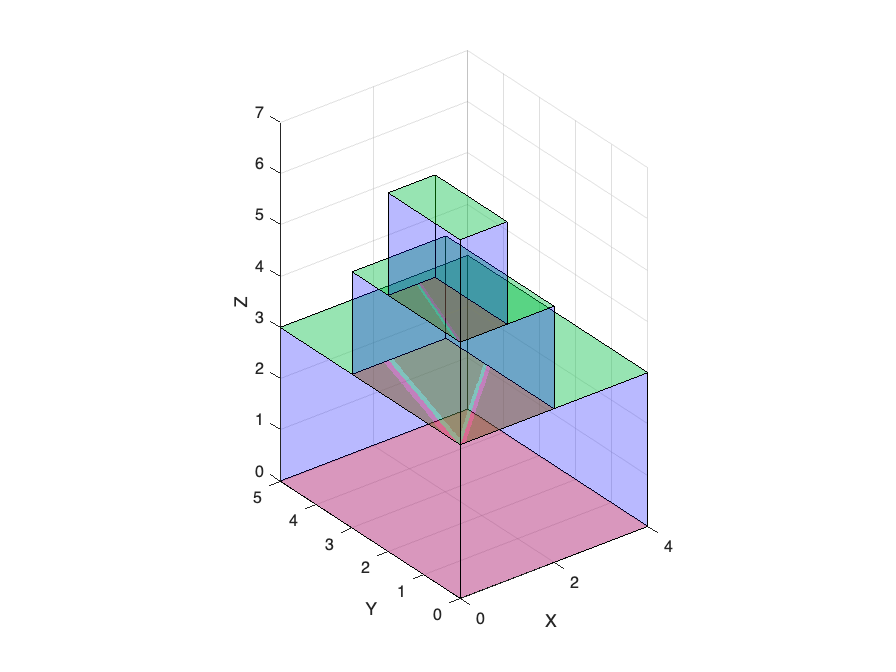

clear;clc;
Boxes = {[4, 5, 3], [1, 5, 4], [2, 3, 2], [2, 4, 1], [3, 6, 2], [1, 2, 2]};

%%% reordering boxes solution %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Extract the third coordinate (heights)
widths = cellfun(@(x)x(2), Boxes);
% Sort heights and get sort indices
[~, idx] = sort(widths);
% Reorder Boxes accordingly
Boxes = Boxes(idx);

%%% implementation %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

N = length(Boxes);

nb_points = N; % number of points has diret impact on accuary
% xs = linspace(0,1,nb_points)'; boxes

g_k = @(Box) -Box(3);
g_N = g_k;

mu=NaN*zeros(nb_points,N); 
J=zeros(nb_points,N+1);  

for i = 1:nb_points 

    J(i,N+1) = g_N(Boxes{i}); % always zero

end

for i = N:-1:1 %over all time 

    for ii = 1:nb_points % over all states in current time

       us = Boxes(1:ii);
       nb_pos = length(us);
       J_temp = [];

       for iii=1:nb_pos % over all avaible decisions in current state and time 

            x_next = us{iii};

            if (Boxes{ii}(1) > x_next(1) && Boxes{ii}(2) > x_next(2)) && ii~=iii
                J_temp(iii) = g_k(Boxes{ii}) + J(iii,i+1);
            else
                J_temp(iii) = 0;
            end

       end

       %%%%%%% BEST APPROACH IN CURRENT STATE AND TIME 
       [maxval,maxpos] = min([J_temp J(ii,i+1)]);

       if(maxval == 0 || maxval == J(ii,i+1))
          J(ii,i) = maxval; mu(ii,i) = NaN;
       else
          J(ii,i) = max(maxval); mu(ii,i) = maxpos;
       end

    end 

end 


%%% Extract solution %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[~, row] = min(J(:,1));
solution{1}=Boxes{row};
count = 2 ;

for i = 1:length(Boxes)
    if(~isnan(mu(row,i)))
        solution{count} = Boxes{mu(row,i)};
        row = mu(row,i);
        count = count + 1;
    end
end


%%% print solution %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
start_z = 0; % initial z-coordinate
figure;
hold on;

for k = 1:length(solution)
    b = solution{k};
    width = b(1); length_ = b(2); height = b(3);
    % Coordinates of box corners
    X = [0 width width 0 0 width width 0];
    Y = [0 0 length_ length_ 0 0 length_ length_];
    Z = [start_z start_z start_z start_z start_z+height start_z+height start_z+height start_z+height];
    
    % Draw bottom face
    fill3(X(1:4),Y(1:4),Z(1:4),'r','FaceAlpha',0.3);
    % Draw top face
    fill3(X(5:8),Y(5:8),Z(5:8),'g','FaceAlpha',0.3);
    
    % Draw vertical sides
    for ii = 1:4
        idx = [ii, mod(ii,4)+1, mod(ii,4)+5, ii+4];
        fill3(X(idx), Y(idx), Z(idx), 'b', 'FaceAlpha',0.15);
    end
    
    start_z = start_z + height; % Move up for next box
end

xlabel('X'); ylabel('Y'); zlabel('Z');
view(3);
axis equal; grid on; hold off;